clear 
clc 
close all

## **Reading data recorded from magnetic testbed**

%%%Add raw data from magnetometer
load('staticMagData_Epoch_2024_01_04.mat');
time = staticDataStore(1,925:end-1);
Bx = staticDataStore(2,925:end-1); By = staticDataStore(3,925:end-1); Bz = staticDataStore(4,925:end-1);
%%Remove NAN values
staticMeasures.time = time(~isnan(time));
staticMeasures.Bx   = Bx(~isnan(Bx));
staticMeasures.By   = By(~isnan(By));
staticMeasures.Bz   = Bz(~isnan(Bz));

%%%Add data with increasing current
load('xCoil_Epoch_2024_01_14.mat');
time = x_coil_data(1,:);
Bx = x_coil_data(2,:); By = x_coil_data(3,:); Bz = x_coil_data(4,:);
V  = x_coil_data(5,:); I  = x_coil_data(6,:);
%%Data
xcoil.data_up.time = time(~isnan(time));
xcoil.data_up.Bx = Bx(~isnan(Bx)); 
xcoil.data_up.By = By(~isnan(By)); 
xcoil.data_up.Bz = Bz(~isnan(Bz));
xcoil.data_up.V  = V(~isnan(V)); 
xcoil.data_up.I  = I(~isnan(I));

%%%Add data with decreasing current
load('xCoil_Epoch_2024_01_14_t1.mat');
time = x_coil_data(1,:);
Bx = x_coil_data(2,:); By = x_coil_data(3,:); Bz = x_coil_data(4,:);
V  = x_coil_data(5,:); I  = x_coil_data(6,:);
%%Data
xcoil.data_down.raw.time = time(~isnan(time));
xcoil.data_down.raw.Bx = Bx(~isnan(Bx)); 
xcoil.data_down.raw.By = By(~isnan(By)); 
xcoil.data_down.raw.Bz = Bz(~isnan(Bz));
xcoil.data_down.raw.V  = V(~isnan(V)); 
xcoil.data_down.raw.I  = I(~isnan(I));
%%%Interpolated data
[xcoil.data_down.int.time, xcoil.data_down.int.Bx] = setSampleTime(xcoil.data_down.raw.time,xcoil.data_down.raw.Bx,0.2);
[xcoil.data_down.int.time, xcoil.data_down.int.By] = setSampleTime(xcoil.data_down.raw.time,xcoil.data_down.raw.By,0.2);
[xcoil.data_down.int.time, xcoil.data_down.int.Bz] = setSampleTime(xcoil.data_down.raw.time,xcoil.data_down.raw.Bz,0.2);
[xcoil.data_down.int.time, xcoil.data_down.int.V] = setSampleTime(xcoil.data_down.raw.time,xcoil.data_down.raw.V,0.2);
[xcoil.data_down.int.time, xcoil.data_down.int.I] = setSampleTime(xcoil.data_down.raw.time,xcoil.data_down.raw.I,0.2);

**Check Data**

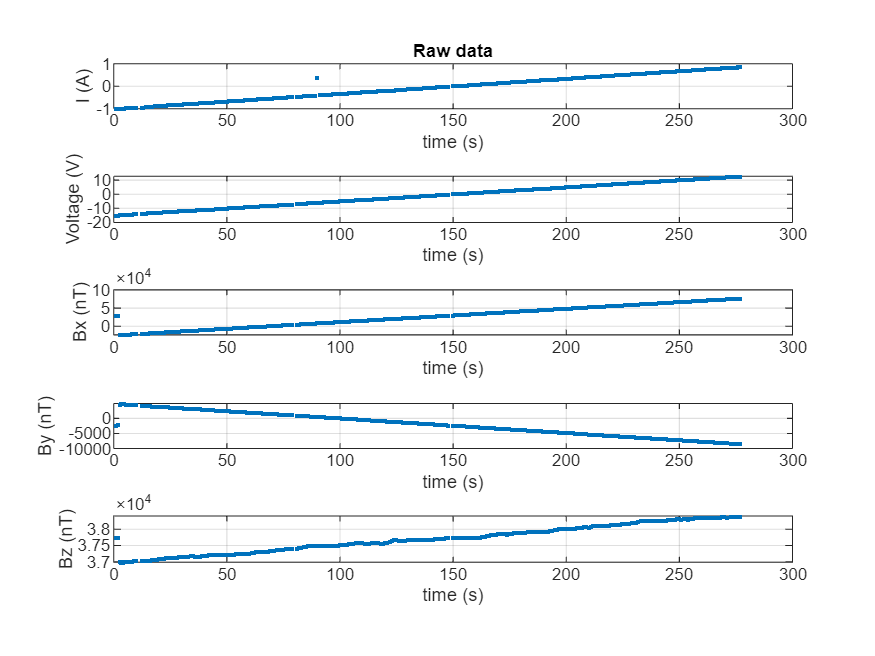

figure()
p1 = subplot(5,1,1);
    h1 = plot(xcoil.data_up.time,xcoil.data_up.I,'.');
    %h2 = plot
    title('Raw data'); xlabel('time (s)'); ylabel('I (A)');grid on;
p2 = subplot(5,1,2);
    h2 = plot(xcoil.data_up.time,xcoil.data_up.V,'.');
    xlabel('time (s)'); ylabel('Voltage (V)');grid on;
p3 = subplot(5,1,3);
    h3 = plot(xcoil.data_up.time,xcoil.data_up.Bx,'.');
    xlabel('time (s)'); ylabel('Bx (nT)');grid on;
p4 = subplot(5,1,4);
    h4 = plot(xcoil.data_up.time,xcoil.data_up.By,'.');
    xlabel('time (s)'); ylabel('By (nT)');grid on;
p5 = subplot(5,1,5);
    h5 = plot(xcoil.data_up.time,xcoil.data_up.Bz,'.');
    xlabel('time (s)'); ylabel('Bz (nT)');grid on;
    linkaxes([p1,p2,p3,p4,p5],'x');

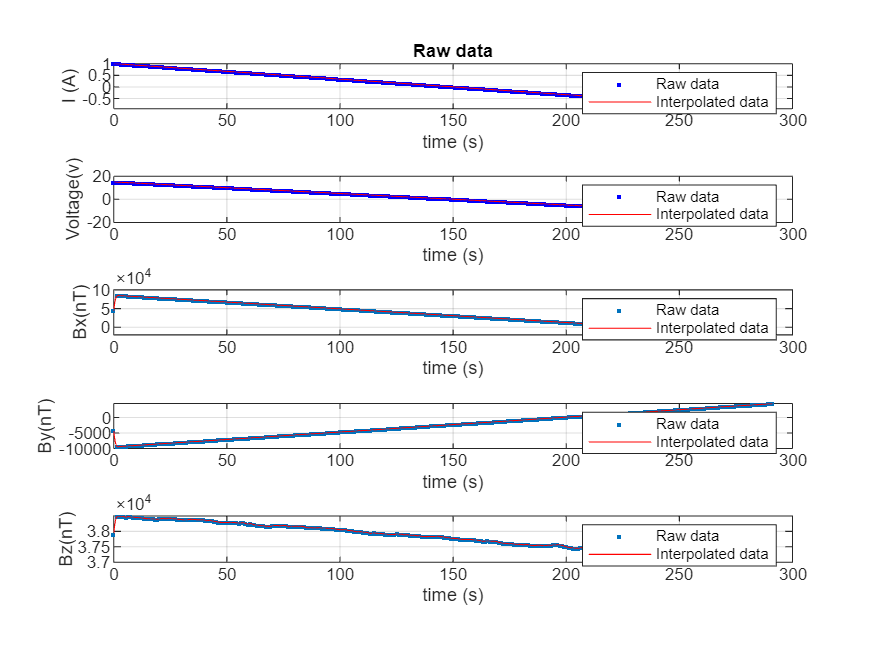

figure()
p1 = subplot(5,1,1);
    h1 = plot(xcoil.data_down.raw.time,xcoil.data_down.raw.I,'b.'); hold on;
    h2 = plot(xcoil.data_down.int.time,xcoil.data_down.int.I,'r-');
    legend([h1,h2],'Raw data','Interpolated data')
    title('Raw data'); xlabel('time (s)'); ylabel('I (A)');grid on;
p2 = subplot(5,1,2);
    h3 = plot(xcoil.data_down.raw.time,xcoil.data_down.raw.V,'b.'); hold on;
    h4 = plot(xcoil.data_down.int.time,xcoil.data_down.int.V,'r-');
    legend([h3,h4],'Raw data','Interpolated data');
    xlabel('time (s)'); ylabel('Voltage(v)');grid on;
p3 = subplot(5,1,3);
    h5 = plot(xcoil.data_down.raw.time,xcoil.data_down.raw.Bx,'.'); hold on;
    h6 = plot(xcoil.data_down.int.time,xcoil.data_down.int.Bx,'r-');
    legend([h5,h6],'Raw data','Interpolated data');
    xlabel('time (s)'); ylabel('Bx(nT)');grid on;
p4 = subplot(5,1,4);
    h7 = plot(xcoil.data_down.raw.time,xcoil.data_down.raw.By,'.'); hold on;
    h8 = plot(xcoil.data_down.int.time,xcoil.data_down.int.By,'r-');
    legend([h7,h8],'Raw data','Interpolated data');
    xlabel('time (s)'); ylabel('By(nT)');grid on;
p5 = subplot(5,1,5);
    h9  = plot(xcoil.data_down.raw.time,xcoil.data_down.raw.Bz,'.'); hold on;
    h10 = plot(xcoil.data_down.int.time,xcoil.data_down.int.Bz,'r-');
    legend([h9,h10],'Raw data','Interpolated data');
    xlabel('time (s)'); ylabel('Bz(nT)');grid on;
    linkaxes([p1,p2,p3,p4,p5],'x');

## **Setting Parameters**

### **For Z axis**

IS501NMTB.Z.L = 1.03;
IS501NMTB.Z.a = IS501NMTB.Z.L/2 ;
%IS501NMTB.Z.h = 0.5 ;
IS501NMTB.Z.h = 1.03 ;
IS501NMTB.Z.N = 59.12; 

### **For Y axis**

IS501NMTB.Y.L = 1.02;
IS501NMTB.Y.a = IS501NMTB.Y.L/2 ;
IS501NMTB.Y.h = 0.5 ;
IS501NMTB.Y.N = 111.2; 

### **For X axis**

IS501NMTB.X.L = 1.03;
IS501NMTB.X.a = IS501NMTB.X.L/2 ;
%IS501NMTB.X.h = 0.5;
IS501NMTB.X.h = 1.03;
IS501NMTB.X.N = 97.18;

## Static measurements

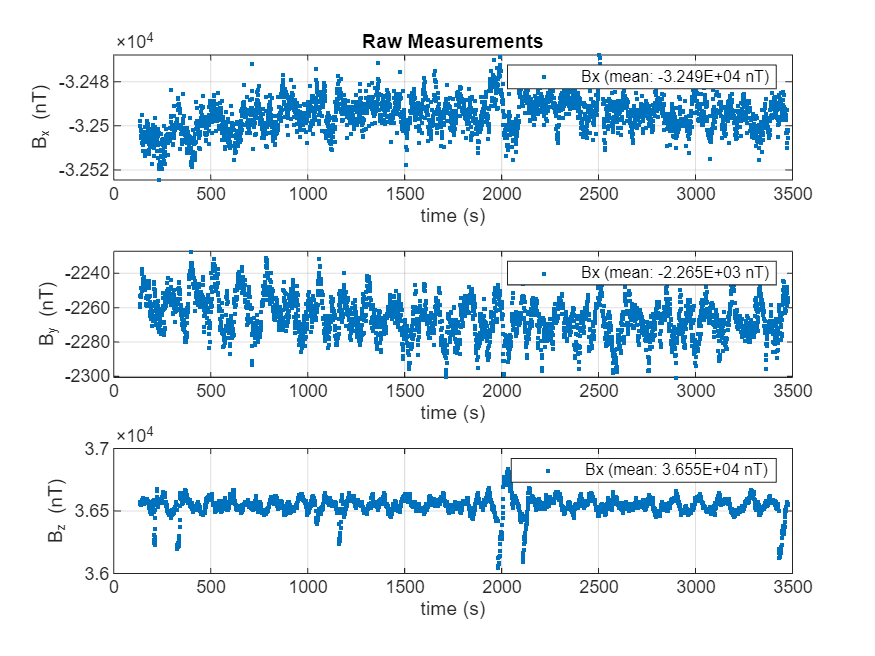

%%%Recover data with coils off
figure()
%%%Get mean values
Bxreal_mean = mean(staticMeasures.Bx);
Byreal_mean = mean(staticMeasures.By);
Bzreal_mean = mean(staticMeasures.Bz);

subplot(3,1,1)
    h1 = plot(staticMeasures.time, staticMeasures.Bx,'.'); grid on;
    title('Raw Measurements'); legend(h1, ['Bx (mean: ',num2str(Bxreal_mean,'%.3E'),' nT)']);
    xlabel('time (s)'); ylabel('B_x (nT)'); 

subplot(3,1,2)
    h2 = plot(staticMeasures.time, staticMeasures.By,'.'); grid on;
    legend(h2, ['Bx (mean: ',num2str(Byreal_mean,'%.3E'),' nT)']);
    xlabel('time (s)'); ylabel('B_y (nT)'); 

subplot(3,1,3)
    h3 = plot(staticMeasures.time, staticMeasures.Bz,'.'); grid on;
    legend(h3, ['Bx (mean: ',num2str(Bzreal_mean,'%.3E'),' nT)']);
    xlabel('time (s)'); ylabel('B_z (nT)');   

Analize data

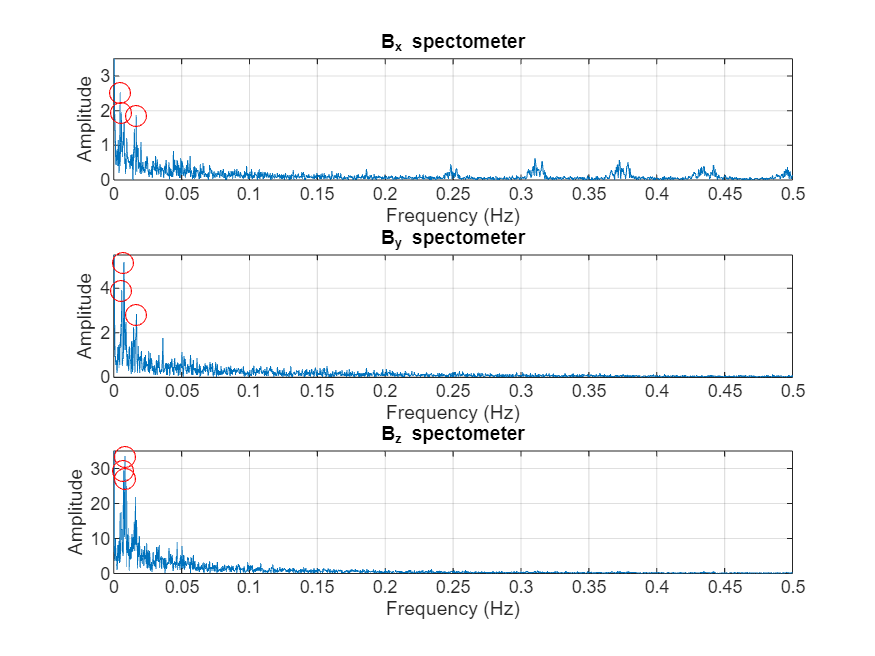

figure()
subplot(3,1,1)
    [gx, top_three_pks_Bx, top_three_freq_Bx, constant_Bx, t_uniform_Bx, x_uniform_Bx] = fftAalisys(staticMeasures.time,staticMeasures.Bx);
    title('B_x spectometer'); xlim([0 0.5]); ylim([0 3.5]);
subplot(3,1,2)
    [gy, top_three_pks_By, top_three_freq_By, constant_By, t_uniform_By, x_uniform_By] = fftAalisys(staticMeasures.time,staticMeasures.By);
    title('B_y spectometer'); xlim([0 0.5]); ylim([0 5.5]);
subplot(3,1,3)
    [gz, top_three_pks_Bz, top_three_freq_Bz, constant_Bz, t_uniform_Bz, x_uniform_Bz] = fftAalisys(staticMeasures.time,staticMeasures.Bz);
    title('B_z spectometer'); xlim([0 0.5]); ylim([0 35]);

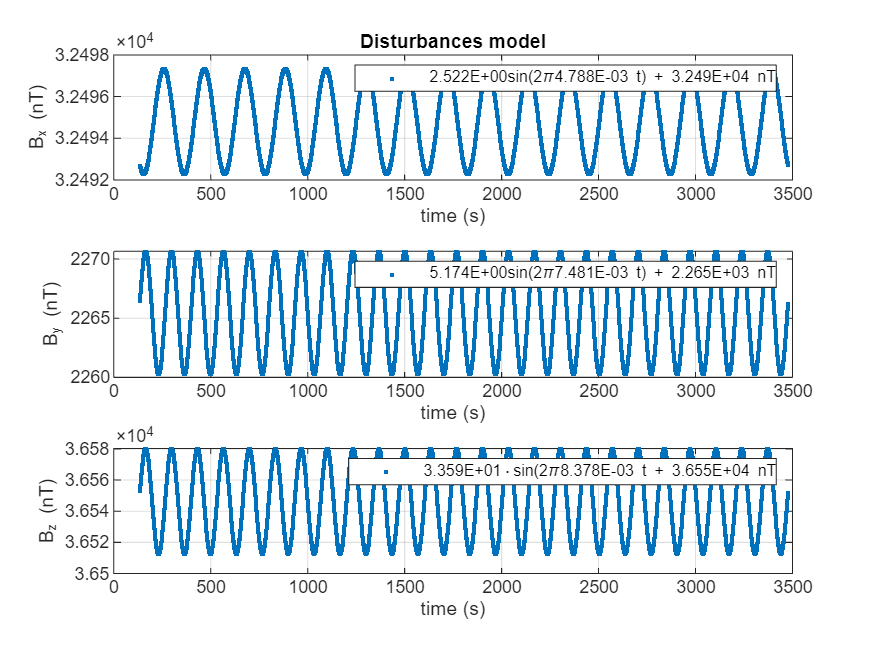

%%%Calculate disturbances model for the Heltholtz cage
    x_disturbances = constant_Bx + top_three_pks_Bx(1)*sin(2*pi*top_three_freq_Bx(1)*t_uniform_Bx);
    y_disturbances = constant_By + top_three_pks_By(1)*sin(2*pi*top_three_freq_By(1)*t_uniform_Bz);
    z_disturbances = constant_Bz + top_three_pks_Bz(1)*sin(2*pi*top_three_freq_By(1)*t_uniform_Bz);

%%%Plot disturbances
   figure()
   subplot(3,1,1)
    h1 = plot(t_uniform_Bx, x_disturbances,'.'); grid on;
    title('Disturbances model'); 
    legend(h1, [num2str(top_three_pks_Bx(1),'%.3E') 'sin(2\pi',num2str(top_three_freq_Bx(1),'%.3E'),' t) + ', num2str(constant_Bx,'%.3E'), ' nT']);
    xlabel('time (s)'); ylabel('B_x (nT)'); 

subplot(3,1,2)
    h2 = plot(t_uniform_By, y_disturbances,'.'); grid on;
    legend(h2, [num2str(top_three_pks_By(1),'%.3E') 'sin(2\pi',num2str(top_three_freq_By(1),'%.3E'),' t) + ', num2str(constant_By,'%.3E'), ' nT']);
    xlabel('time (s)'); ylabel('B_y (nT)'); 

subplot(3,1,3)
    h3 = plot(t_uniform_Bz, z_disturbances,'.'); grid on;
    legend(h3, [num2str(top_three_pks_Bz(1),'%.3E') '\cdotsin(2\pi',num2str(top_three_freq_Bz(1),'%.3E'),' t + ', num2str(constant_Bz,'%.3E'), ' nT']);
    xlabel('time (s)'); ylabel('B_z (nT)');   

Compare design disturbances with the real disturbances.

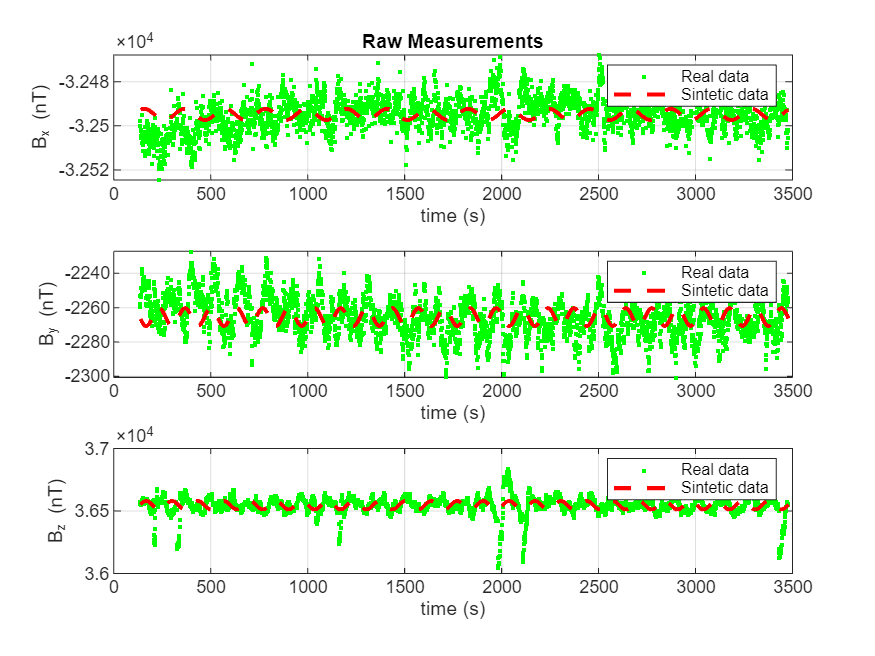

figure() 
subplot(3,1,1)
    h1 = plot(staticMeasures.time, staticMeasures.Bx,'g.'); hold on; grid on;
    h2 = plot(t_uniform_Bx, -1*x_disturbances,'r--','LineWidth',2);
    title('Raw Measurements');
    legend([h1, h2], 'Real data','Sintetic data');
    xlabel('time (s)'); ylabel('B_x (nT)'); 

subplot(3,1,2)
    h3 = plot(staticMeasures.time, staticMeasures.By,'g.'); hold on; grid on;
    h4 = plot(t_uniform_Bx, -1*y_disturbances,'r--','LineWidth',2);
    legend([h3, h4], 'Real data','Sintetic data');
    xlabel('time (s)'); ylabel('B_y (nT)'); 

subplot(3,1,3)
    h5 = plot(staticMeasures.time, staticMeasures.Bz,'g.'); hold on; grid on;
    h6 = plot(t_uniform_Bx, z_disturbances,'r--','LineWidth',2);
    legend([h5, h6], 'Real data','Sintetic data');
    xlabel('time (s)'); ylabel('B_z (nT)');   

## **Simulation**

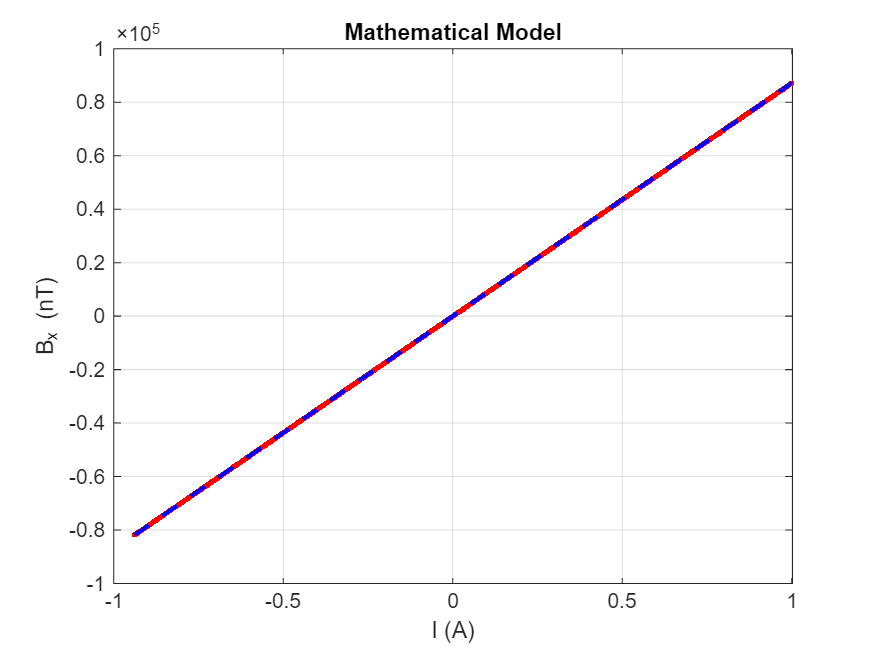

%%%Simulated data 
%%%Biot Savart law at x=0
mu_0 = 4*pi*1e-7;    % Permeability in the vacum
functBxyz0 = @(N,I,a,h) (4 * mu_0 * N *I * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));

%%%Start simulation at x=0
simulated.Iarr = xcoil.data_down.int.I;
simulated.B_x = functBxyz0(IS501NMTB.X.N, simulated.Iarr, IS501NMTB.X.a, IS501NMTB.X.h)*1E9; %% In (nT)
%%%Linear Regresion
%%%Perform linear regression of degree 1 (a straight line)
degree_of_polynomial = 1;
coeffs = polyfit(simulated.Iarr, simulated.B_x, degree_of_polynomial);
%%%Coeffs will contain the coefficients of the fitted polynomial (in this case, the slope and intercept)
slope = coeffs(1); intercept = coeffs(2);

x_fit = linspace(min(simulated.Iarr), max(simulated.Iarr), 50); %%% x values for the regression line
y_fit = polyval(coeffs, x_fit); % Calculate fitted y values


figure()
plot(simulated.Iarr,simulated.B_x,'r.'); hold on; grid on
plot(x_fit, y_fit, 'b--','LineWidth',2); % Linear regression line
title('Mathematical Model');
xlabel('I (A)'); ylabel('B_x (nT)');

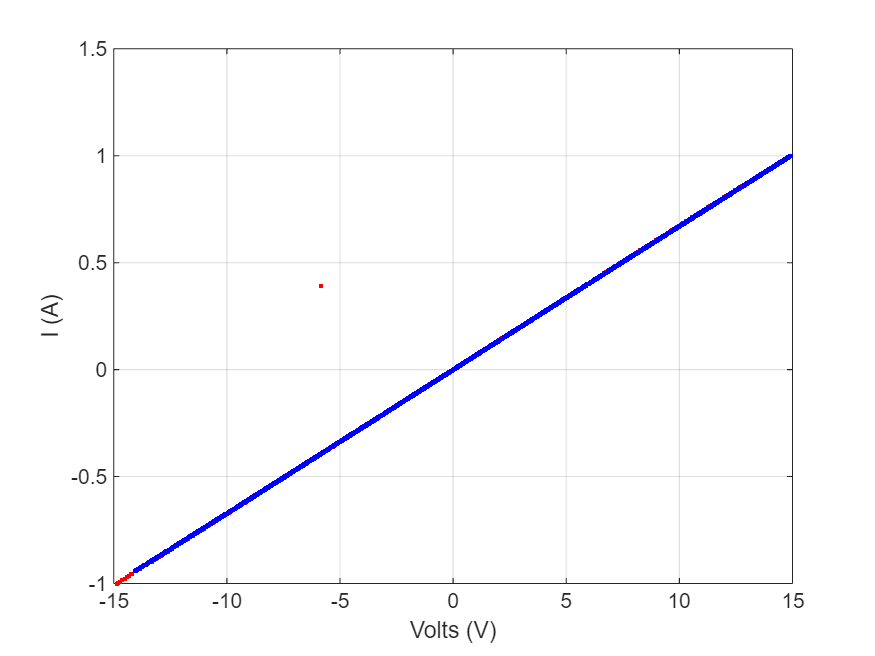

%%%Real data
figure
    plot(xcoil.data_up.V,xcoil.data_up.I,'r.'); hold on; grid on;
    plot(xcoil.data_down.int.V,xcoil.data_down.int.I,'b.'); 
    xlabel('Volts (V)'); ylabel('I (A)');

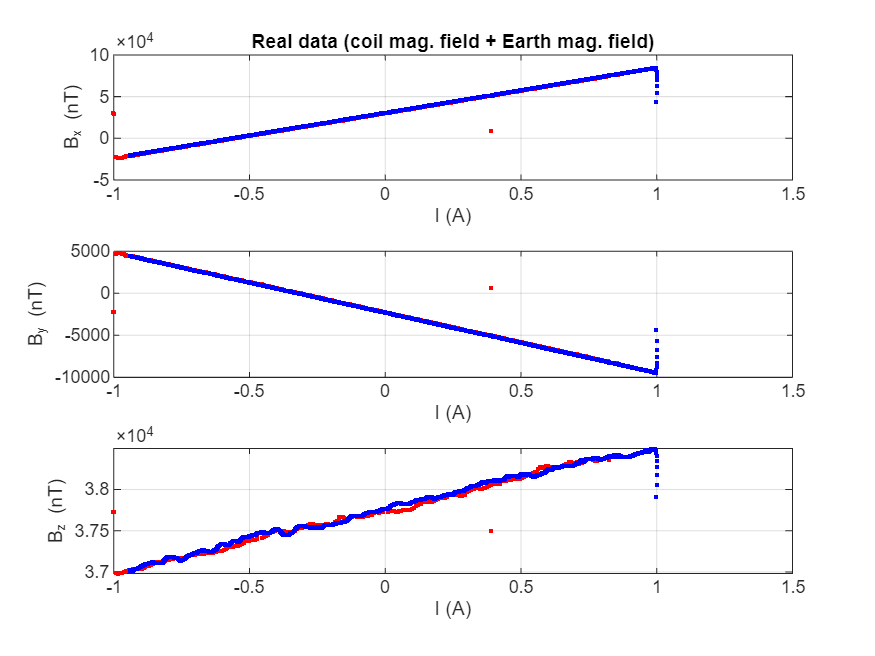

figure
subplot(3,1,1)
    plot(xcoil.data_up.I,xcoil.data_up.Bx,'r.'); hold on; grid on;
    plot(xcoil.data_down.int.I,xcoil.data_down.int.Bx,'b.');
    title('Real data (coil mag. field + Earth mag. field)');
    xlabel('I (A)'); ylabel('B_x (nT)');
subplot(3,1,2)
    plot(xcoil.data_up.I,xcoil.data_up.By,'r.'); hold on; grid on;
    plot(xcoil.data_down.int.I,xcoil.data_down.int.By,'b.');
    xlabel('I (A)'); ylabel('B_y (nT)');
subplot(3,1,3)
    plot(xcoil.data_up.I,xcoil.data_up.Bz,'r.'); hold on; grid on;
    plot(xcoil.data_down.int.I,xcoil.data_down.int.Bz,'b.'); 
xlabel('I (A)'); ylabel('B_z (nT)');

## Real **plant** stimation

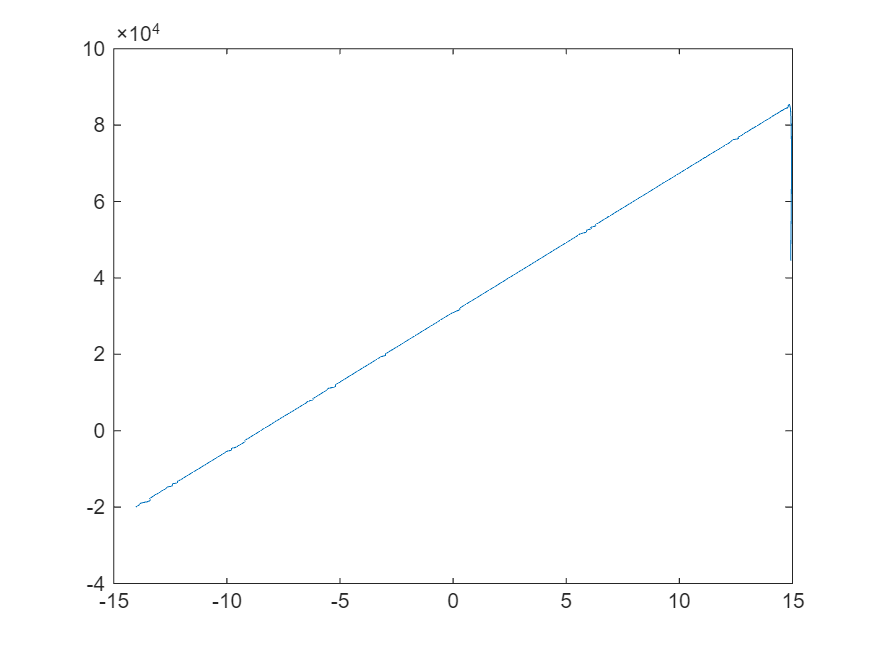

%%% Prepare data for identification
input  = xcoil.data_down.int.V';
output = xcoil.data_down.int.Bx';
figure()
plot(input,output)

figure()

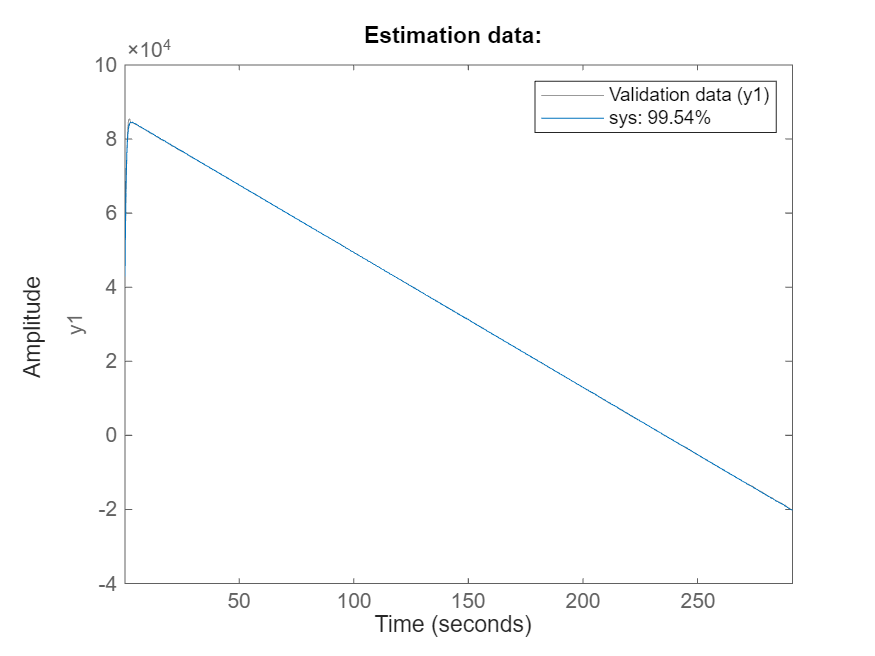

% Create object for time-series data
estimationData = iddata(output,input,0.2);

% Estimate process model
sys = procest(estimationData,'P2Z');

% Display results
compare(estimationData,sys);
clear estimationData;
title('Estimation data:');

sys

sys =
 
Process model with transfer function:
                   1+Tz*s            
  G(s) = Kp * ------------------     
              (1+Tp1*s)(1+Tp2*s)     
                                     
         Kp = 3639.2                 
        Tp1 = 108.65                 
        Tp2 = 0.52435                
         Tz = 24.199                 
                                     
Parameterization:
    {'P2Z'}
   Number of free coefficients: 4
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                      
Estimated using PROCEST on time domain data "estimationData".
Fit to estimation data: 99.54%                               
FPE: 1.988e+04, MSE: 1.971e+04                               
 


%% tur
%%turno into ss
systf = tf(sys);
[A,B,C,D] = tf2ss(systf.Numerator{1, 1}, systf.Denominator{1, 1});
disp('A:'); disp(A); disp('B:'); disp(B); disp('C:'); disp(C); disp('D:'); disp(D);

A:
   -1.9163   -0.0176
    1.0000         0

B:
     1
     0

C:
   1.0e+03 *

    1.5458    0.0639

D:
     0



**Controller Design**

- **Open Loop evaluation**

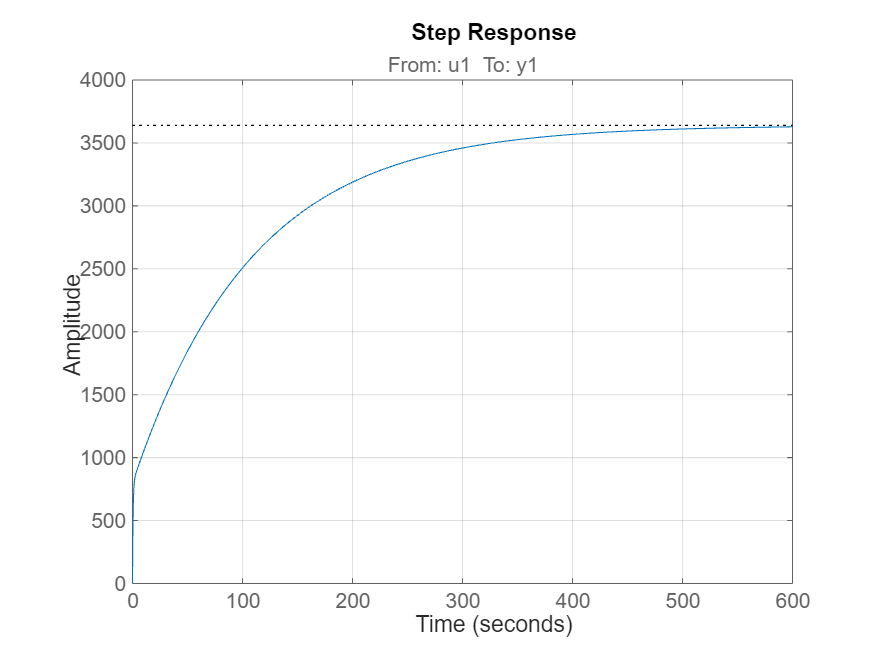

step(sys);grid on;

% Obtener información sobre la respuesta al escalón
info = stepinfo(sys)

info = struct with fields:
         RiseTime: 223.0175
    TransientTime: 398.1953
     SettlingTime: 398.1953
      SettlingMin: 3.2754e+03
      SettlingMax: 3.6325e+03
        Overshoot: 0
       Undershoot: 0
             Peak: 3.6325e+03
         PeakTime: 657.7182


- Close Loop

## PID controller

PID = pidtune(sys,'PID');
disp('kp');disp(PID.Kp); disp('kd');disp(PID.Kd); disp('ki');disp(PID.Ki);

kp
   1.4605e-04

kd
     0

ki
   1.0648e-05



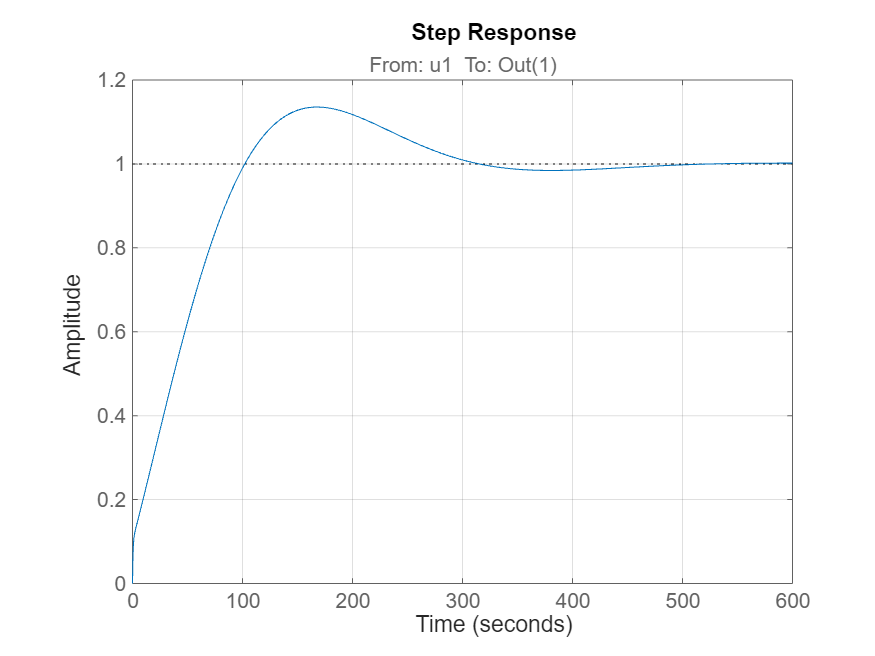

%%%close loops
closeLoop = feedback(PID*sys,1);                                    
step(closeLoop); grid on;

info = stepinfo(closeLoop)

info = struct with fields:
         RiseTime: 83.2059
    TransientTime: 286.6470
     SettlingTime: 286.6470
      SettlingMin: 0.9002
      SettlingMax: 1.1354
        Overshoot: 13.5445
       Undershoot: 0
             Peak: 1.1354
         PeakTime: 167.7708


- Real time simulation

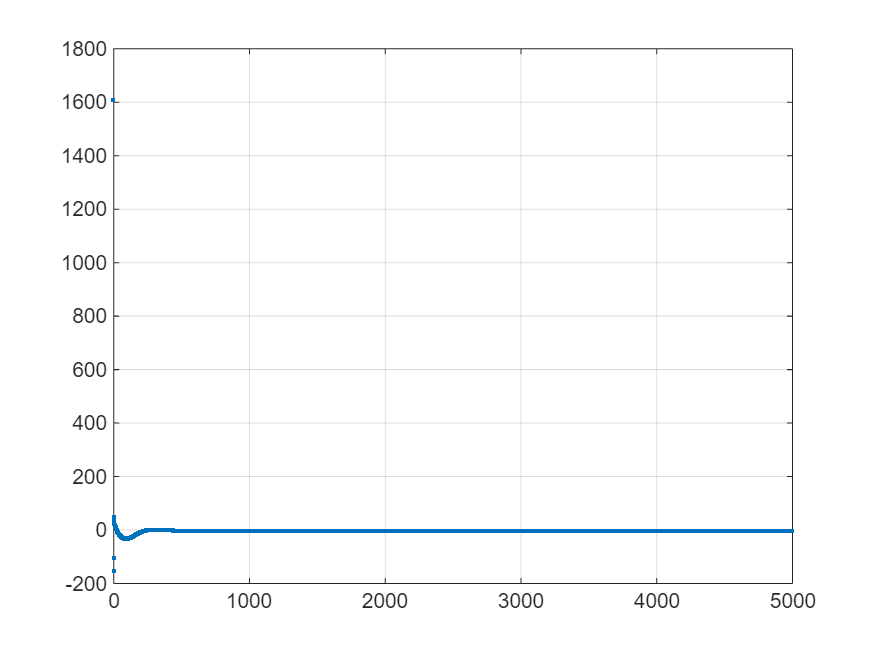

%%Simulation settings
dt        = 1; %%s
finalTime = 5000;
setpoint = 0; 

%% Progress bar
settings.hWaitbar = waitbar(0, 'Progress: 0%','Name', 'IS501 MagneticTestBed');


%%create a timevector
t = 0:dt:finalTime;

%%calculate disturbances in advance
%Tdis = disturbance(t);

%%Containers
x = zeros(2,length(t));
y = zeros(1,length(t));
u = zeros(1,length(t)); 

%%Initial conditions
x(:,1) = [1,1]';
y(1)   = C*x(:,1);
integralvalue = 0;
prev_error = 0;

%%PID gains
Kp = 1.460477259865257e-04;
Ki = 1.064753047190848e-05;
Kd = 0;

for i=1:length(t)
    %%%PID controller
    % Calculate error
    error = setpoint - y(i);
    
    % Proportional term
    P = Kp * error;
    
    % Integral term
    integralvalue = integralvalue + Ki * error * dt;
    
    % Derivative term
    derivative = Kd * (error - prev_error) / dt;
    
    % PID control law
    u(i) = P + integralvalue + derivative;
    
    
    %Empezamos en RK 4 de cuarto orden
    g1=dt*xcoilfun(t(i), x(:,i), u(i),A,B);
    g2=dt*xcoilfun(t(i), x(:,i)+0.5.*g1, u(i),A,B);
    g3=dt*xcoilfun(t(i), x(:,i)+0.5.*g2, u(i),A,B);
    g4=dt*xcoilfun(t(i), x(:,i)+0.5.*g3, u(i),A,B);
    x(:,i+1)=x(:,i)+(1/6).*(g1+2.*g2+2.*g3+g4);
    y(i+1)=C*x(:,i)+D*u(i);
    
    %%% Progress bar configuration
    %%%% Calculate the progress percentage
    progress = t(i) / finalTime;
    
    if isa(settings.hWaitbar,'handle') && isvalid(settings.hWaitbar)
        if t(i) == t(end)
            % Close the progress bar when the simulation is complete
            close(settings.hWaitbar);
        else
            % Update the progress bar
            waitbar(progress, settings.hWaitbar, sprintf('Progress: %.1f%%', progress*100));
        end
    end
prev_error = error;
end

figure()
plot(t,y(1:end-1),'.');grid on;

## Adaptive control (Model Reference Model

%%Set reference moded
% Desired settling time and steady-state error
% Desired specifications
desired_settling_time = 100.0;       % in seconds
desired_steady_state_error = 0.05; % 5% steady-state error
desired_overshoot = 0.1;            % 10% overshoot

% Calculate natural frequency and damping ratio
wn = 4 / (desired_settling_time * pi);
zeta = -log(desired_overshoot/100) / sqrt(pi^2 + (log(desired_overshoot/100))^2);

% Calculate proportional gain for steady-state error
ess = desired_steady_state_error / (1 - desired_steady_state_error);
Kp = (1 / ess - 1)*(1/18);

% Define the transfer function
numerator = [Kp * wn^2, Kp * wn^2];
denominator = [1 2*zeta*wn wn^2];
sys_second_order = tf(numerator, denominator);

% Display the transfer function
disp('Transfer function with desired specifications:');

Transfer function with desired specifications:


disp(sys_second_order);

  tf with properties:

       Numerator: {[0 1.6211e-04 1.6211e-04]}
     Denominator: {[1 0.0232 1.6211e-04]}
        Variable: 's'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [0]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



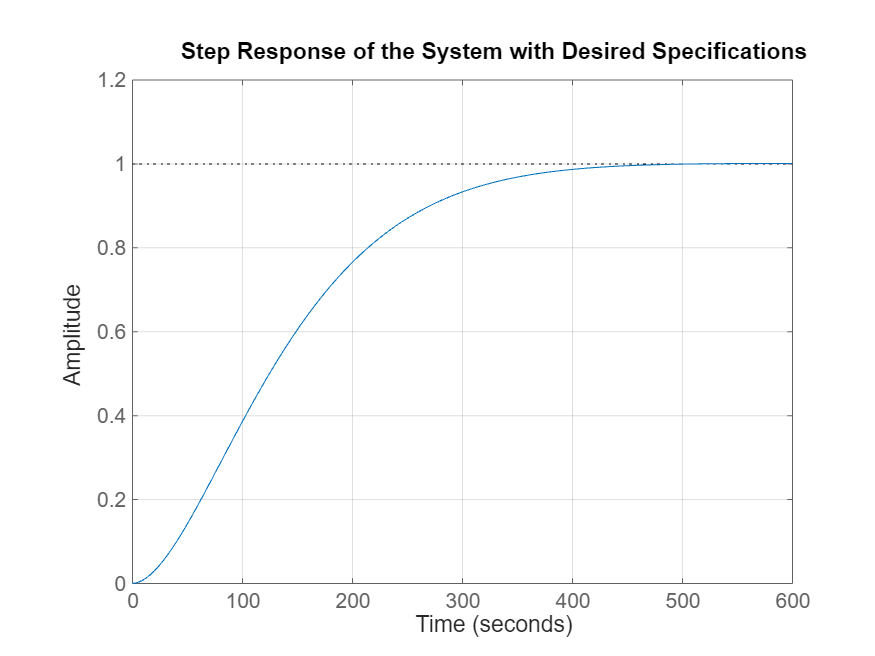

step(sys_second_order);
title('Step Response of the System with Desired Specifications');
xlabel('Time');
ylabel('Amplitude');
grid on;

stepinfo(sys_second_order)

ans = struct with fields:
         RiseTime: 230.0782
    TransientTime: 376.9519
     SettlingTime: 376.9519
      SettlingMin: 0.9051
      SettlingMax: 1.0010
        Overshoot: 0.1000
       Undershoot: 0
             Peak: 1.0010
         PeakTime: 596.0064


%%% Based on second orden, propose a model reference in form 
%%%%% ym=km(s+bm)/(s^2+am1*s+am2)
km=Kp * wn^2;
bm=1;
am1=2*zeta*wn;
am2=wn^2;
numerator = [km km*bm];
denominator = [1 am1 am2];
referenceModel = tf(numerator, denominator);

% Display the step response
stepinfo(referenceModel)

ans = struct with fields:
         RiseTime: 230.0782
    TransientTime: 376.9519
     SettlingTime: 376.9519
      SettlingMin: 0.9051
      SettlingMax: 1.0010
        Overshoot: 0.1000
       Undershoot: 0
             Peak: 1.0010
         PeakTime: 596.0064


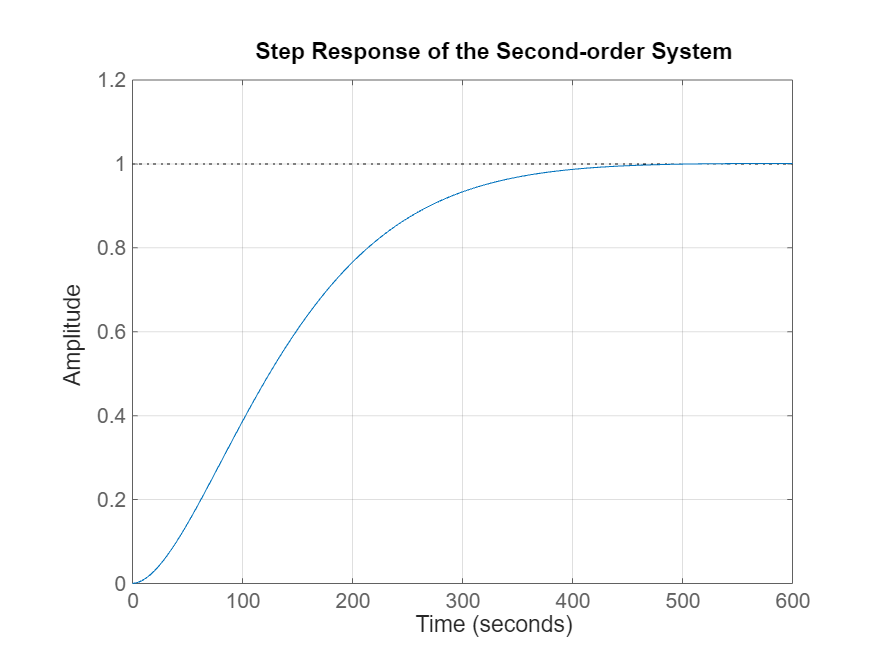


% Plot the step response
step(referenceModel);
title('Step Response of the Second-order System');
xlabel('Time');
ylabel('Amplitude');
grid on;

%%Considering the plant in the form y=kp(s+bp)/(s^2+ap1s+ap2)
Kp = 3639.2;                 
Tp1 = 108.65;                 
Tp2 = 0.52435;                
Tz = 24.199;
bp  = 1/Tz;
kp_model = (Kp*Tz)/(Tp1*Tp2);
ap1 = (Tp1+Tp2)/(Tp1*Tp2);
ap2 = 1/(Tp1*Tp2);
num = [kp_model kp_model*bp];
den = [1 ap1 ap2];
xCoilModel = tf(num, den);

% Display the step response
stepinfo(xCoilModel)

ans = struct with fields:
         RiseTime: 223.0153
    TransientTime: 398.1914
     SettlingTime: 398.1914
      SettlingMin: 3.2754e+03
      SettlingMax: 3.6325e+03
        Overshoot: 0
       Undershoot: 0
             Peak: 3.6325e+03
         PeakTime: 657.7217


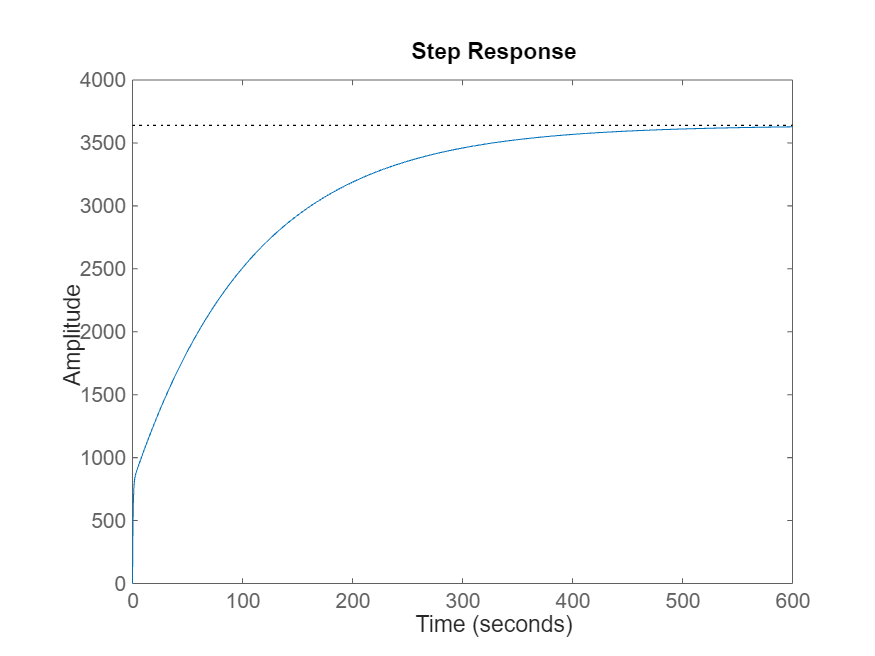

% Display the step response
step(xCoilModel)

Choise of control law

alpha1 = bp-bm;
beta1 = (am1-ap1)/kp_model;
beta2 = (am2-ap2)/kp_model;
k = km/kp_model;

function [grafica, top_three_pks, top_three_freq, constant, t_uniform, x_uniform] = fftAalisys(tout,data)
    %%% Interpolation to have uniform sampling
    temp = diff(tout);               %%Temporal time
    t_sample = mean(temp(1:end-1));                             %%Get sample time
    t_uniform = tout(1):t_sample:tout(end); %%Define a uniform time vector
    %%% Start interpolation
    x_uniform = interp1(tout, data, t_uniform, 'spline');  % Interpolación
     
    % Calcular la FFT de la señal uniforme
    Fs = 1 / (t_uniform(2) - t_uniform(1));  % Frecuencia de muestreo
    L = length(x_uniform);  % Longitud de la señal
    Y = fft(x_uniform);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
     
    % Encontrar los picos
    [pks, locs] = findpeaks(P1);
    % Ordenar los picos en orden descendente por valor
    [sorted_pks, sorted_idx] = sort(pks, 'descend');
    % Seleccionar los tres valores más altos
    top_three_pks = sorted_pks(1:3);
    top_three_locs = locs(sorted_idx(1:3));
    top_three_freq = f(top_three_locs);
    
    %Add constant component
    constant = P1(1);
    
    % Graficar la FFT
    plot(f, P1); hold on;
    plot(top_three_freq, top_three_pks, 'ro', 'MarkerSize', 10);  % Marcadores rojos en los picos
    %title('GWSAT-1 Total Disturbance FFT');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    grid on;
    
    % Devuelves el objeto de la gráfica
    grafica = gcf;
end

function [ t_uniform, x_uniform] = setSampleTime(tout,data,t_sample)
    %%% Interpolation to have uniform sampling
    %temp = diff(tout);               %%Temporal time
    %t_sample = mean(temp(1:end-1));                             %%Get sample time
    t_uniform = tout(1):t_sample:tout(end); %%Define a uniform time vector
    %%% Start interpolation
    x_uniform = interp1(tout, data, t_uniform, 'spline');  % Interpolación
end

function x_dot = xcoilfun(t,x,u,A,B)
    x_dot = A*x+B*u;
end